# **Distributed-parameter transducer model for the stepped-plate parametric array loudspeaker**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

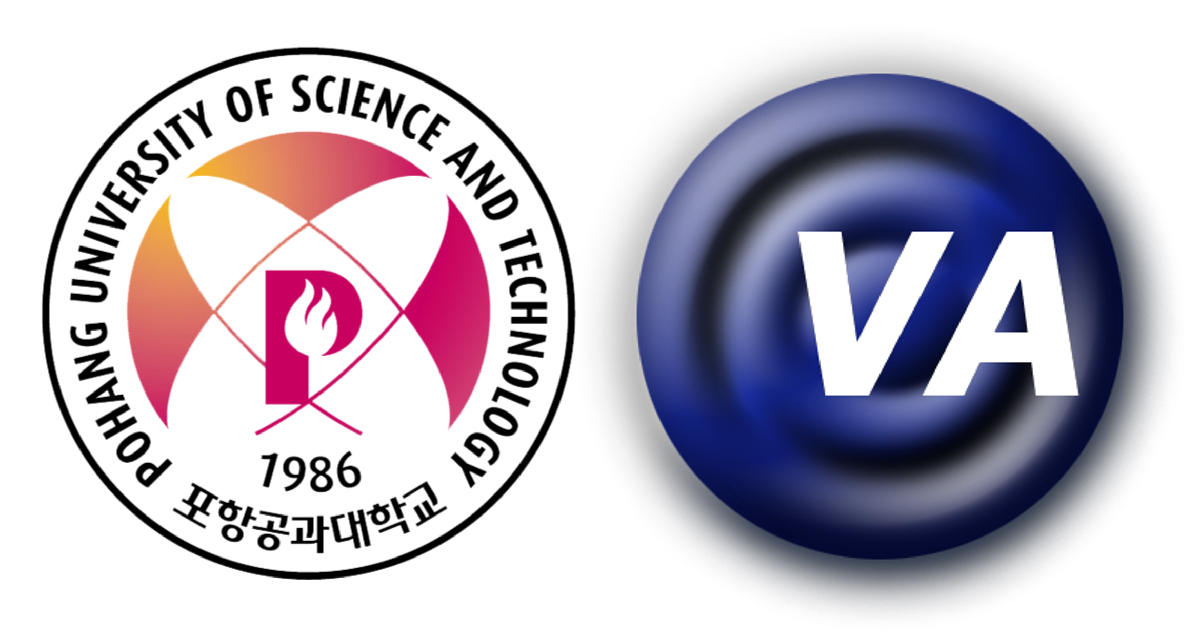

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

Rod

clear

dof = 5; % dof보단 node number가 맞는 것 같은데 진동의 node와 용어가 겹치니 다른 것으로 해야함. 생각해 보자.

rho = sym('rho_%d', [1 dof]);
c   = sym('c_%d', [1 dof]);
k   = sym('k_%d', [1 dof]);
l   = sym('l_%d', [1 dof]);
A   = sym('A_%d', [1 dof]);

u   = sym('u_%d',[1 dof]);

Z_b = sym('Z_b_%d',[1 dof]);
Z_c = sym('Z_c_%d',[1 dof]);
Z_d = sym('Z_d_%d',[1 dof]);

% 수식 Text로 정리할 것
for i=1:dof
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

Z = sym('Z_%d_%d',[dof dof]);

Z(1,1)      = Z_c(1) + Z_d(1);
Z(1,2)      = -Z_b(1);
Z(1,3:dof)  = 0;
for i=2:dof-1
    Z(i,1:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i:i+1));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:dof)= 0;
end
Z(dof, 1:dof-2) = 0;
Z(dof, dof-1)   = -Z_b(dof-1);
Z(dof, dof)     = Z_c(dof) + Z_d(dof);

Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} Z_{d,1}-A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{d,5}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{5}\,c_{5}\,\rho_{5}\,\cot\left(k_{5}\,l_{5}\right)\,\mathrm{i}\\ \sigma_{6}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{7}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i} \end{array}$$